%--------------------------------------------------------------------------
% Title: Market risk measurement, backtesting & Sustainability-related risks
%--------------------------------------------------------------------------
% Author: Erik Hjalmarsson, Arvid Johansson
% Date: February 20, 2024
%--------------------------------------------------------------------------


%--------------------------------------------------------------------------
% Task 1
%--------------------------------------------------------------------------

% Imports
covar = readmatrix('timeSeries.xlsx', 'Sheet', 'VarCor', 'Range', 'C9:Q23');
mean_returns = readmatrix('timeSeries.xlsx', 'Sheet', 'VarCor', 'Range', 'B4:P4');
shareprice_1989 = readmatrix('timeSeries.xlsx', 'Sheet', 'Problem 1 and 2', 'Range', 'C1649:Q1649');
shareprice_2020 = readmatrix('timeSeries.xlsx', 'Sheet', 'Problem 1 and 2', 'Range', 'C3:Q3');
returns = readmatrix('timeSeries.xlsx', 'Sheet', 'Returns', 'Range', 'C2:Q1647');


% Subtask a
n = 15;
assets = repmat(10000000/15, n, 1);
shares = transpose(assets)./shareprice_1989;
portfolio_value_2020 = shareprice_2020*transpose(shares);
portfolio_value_std = 10000000;

weight = repmat(1/15, n, 1); % Constant weight

mean_r = mean(mean_returns);
variance= transpose(weight)*covar*weight;
sigma = sqrt(variance);
VaR_95 = (-mean_r + norminv(0.95)*sigma)*portfolio_value_std;
VaR_975 = (-mean_r + norminv(0.975)*sigma)*portfolio_value_std;
VaR_99 = (-mean_r + norminv(0.99)*sigma)*portfolio_value_std;

disp("VaR_95  = " + VaR_95 + "kr");

VaR_95  = 492324.2891kr


disp("VaR_975 = " + VaR_975 + "kr");

VaR_975 = 591942.954kr


disp("VaR_99  = " + VaR_99 + "kr");

VaR_99  = 707771.1805kr


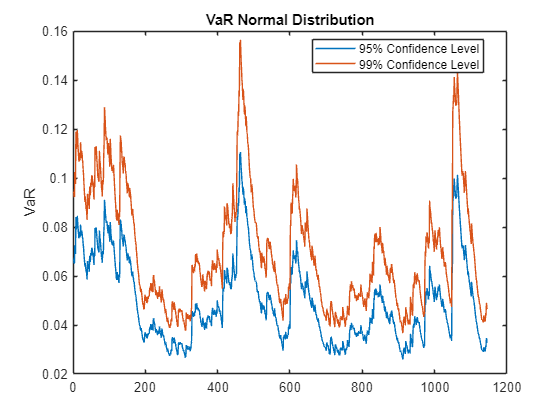

% Subtask b
% Import changing weights
weights = readmatrix('timeSeries.xlsx', 'Sheet', 'Returns', 'Range', 'AJ2:AX1648');
portfolio_returns = flip(readmatrix('timeSeries.xlsx', 'Sheet', 'Returns', 'Range', 'BA2:BA1647'));

log_r = log(1+portfolio_returns);
Lambda = 0.94;
pVar = [0.05 0.01];
vecctortest = zeros(5,1);
TestWindowStart = 502;
TestWindow = TestWindowStart:length(portfolio_returns);
Normal95 = zeros(length(TestWindow), 1);
Normal99 = zeros(length(TestWindow), 1);

variance = zeros(1647, 1);
variance(1) = log_r(1)^2;

% Volatility for the first 502 obs
for i = 2 : (TestWindowStart -1)
    variance(i) = (1-Lambda)*log(1+portfolio_returns(i-1))^2+Lambda*variance(i-1);
end

Zscore = norminv(pVar);

for t = TestWindow 
    k = t - TestWindowStart + 1;
    variance(t) = (1-Lambda)*log(1+portfolio_returns(t-1))^2+Lambda*variance(t-1);
    % Volatility
    Sigma = sqrt(variance(t));
    Normal95(k) = -Zscore(1)*Sigma;
    Normal99(k) = -Zscore(2)*Sigma;
end

figure;
plot(1:1145, [Normal95 Normal99]);
ylabel("VaR");
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best');
title("VaR Normal Distribution");

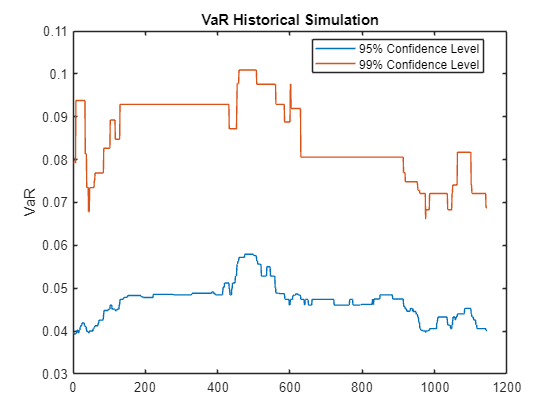

% Subtask c Historical Simulation
Historical95 = zeros(length(TestWindow), 1);
Historical99 = zeros(length(TestWindow), 1);
EstimationWindowSize = 500;

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t - EstimationWindowSize:t-1;
    X = portfolio_returns(EstimationWindow);
    Historical95(i) = -quantile(X,pVar(1));
    Historical99(i) = -quantile(X,pVar(2));
end

figure;
plot(1:1145, [Historical95 Historical99]);
ylabel("VaR");
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best');
title("VaR Historical Simulation");

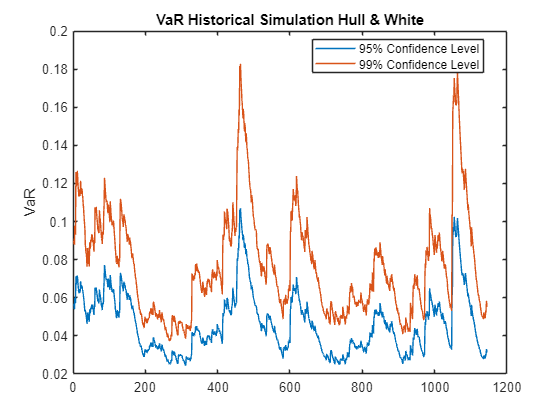

% Subtask d - Hull & White 

log_r = log(1+portfolio_returns);
Lambda = 0.94;
pVar = [0.05 0.01];
HullWhite95 = zeros(length(TestWindow), 1);
HullWhite99 = zeros(length(TestWindow), 1);
epsilon = zeros(length(portfolio_returns), 1);
R_star = zeros(length(TestWindow), 1);

Sigma2_HW = zeros(length(portfolio_returns), 1);
variance = zeros(1647, 1);
TestWindowStart = 502;
variance(1) = log_r(1)^2;

% Initializing sigma
R_bar = 1/20 * sum(portfolio_returns(1:20));
Sigma2_HW(1) = 1/19 * sum((portfolio_returns(1:20)-R_bar).^2);



% Volatility for the whole timeseries
for i = 1 : length(portfolio_returns)
    Sigma2_HW(i+1) = (1-Lambda)*log(1+portfolio_returns(i))^2+Lambda*Sigma2_HW(i);
    epsilon(i) = portfolio_returns(i)/(sqrt(Sigma2_HW(i)));
end

% Multiplying the last 500 values for epsilon with the next calculated
% value for volatility.
for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t - EstimationWindowSize:t-1;
    X = epsilon(EstimationWindow)*sqrt(Sigma2_HW(t));
    HullWhite95(i) = -quantile(X, pVar(1));
    HullWhite99(i) = -quantile(X, pVar(2));
end

figure;
plot(1:1145, [HullWhite95 HullWhite99]);
ylabel("VaR");
legend({'95% Confidence Level','99% Confidence Level'},'Location','Best');
title("VaR Historical Simulation Hull & White");

% Subtask e

% Testing the error rate of the calculated VaRs. Testing whether or not the
% VaR properly forecasts the observed data (i.e VaR 95% should result  in 5
% of 100 observations being worse than VaR)
 vbt = varbacktest(portfolio_returns(502:end), ...
    [Normal95 Normal99 Historical95 Historical99 HullWhite95 HullWhite99], ...
     'PortfolioID','Portfolio',...
       'VaRID',{'Normal95' 'Normal99' 'Historical95' 'Historical99' 'HullWhite95' 'HullWhite99'},...
       'VaRLevel',[0.95 0.99 0.95 0.99 0.95 0.99]);
 
 TestResults_E = bin(vbt, 'TestLevel', 0.95);
 
 disp(TestResults_E);

    PortfolioID        VaRID         VaRLevel     Bin      ZScoreBin    PValueBin    Observations    Failures    TestLevel
    ___________    ______________    ________    ______    _________    _________    ____________    ________    _________

    "Portfolio"    "Normal95"          0.95      accept    -0.98308      0.32557         1145           50         0.95   
    "Portfolio"    "Normal99"          0.99      reject      2.5395     0.011102         1145           20         0.95   
    "Portfolio"    "Historical95"      0.95      accept     0.64409      0.51952         1145           62         0.95   
    "Portfolio"    "Historical99"      0.99      accept      1.0544       0.29


reject_historical_VaR_95 = bin_test(Historical95, portfolio_returns(502:end), 0.95);
reject_historical_VaR_99 = bin_test(Historical95, portfolio_returns(502:end), 0.99);
reject_historical_HW_VaR_95 = bin_test(HullWhite95, portfolio_returns(502:end), 0.95); %too big
reject_historical_HW_VaR_99 = bin_test(HullWhite99, portfolio_returns(502:end), 0.99); %too big
reject_normal_VaR_95 = bin_test(Normal95, portfolio_returns(502:end), 0.95);
reject_normal_VaR_99 = bin_test(Normal99, portfolio_returns(502:end), 0.99);
 

% Subtask f

% CCi tests whether the probability of observing an exception on a
% particular day depends on whether an exception has occured. This can
% check if there are clusterings of observations that are worse than VaR.
% Therefore it can explain the high error rate of the previous step because 
% of the extraordinary circumstances of the financial crisis of 2008. 
TestResults_F = cci(vbt, 'TestLevel', 0.95)

TestResults_F = 6×13 table
    PortfolioID        VaRID         VaRLevel     CCI      LRatioCCI    PValueCCI    Observations    Failures    N00     N10    N01    N11    TestLevel
    ___________    ______________    ________    ______    _________    _________    ____________    ________    ____    ___    ___    ___    _________

    "Portfolio"    "Normal95"          0.95      accept      1.3496      0.24535         1145           50       1048    46     46      4       0.95   
    "Portfolio"    "Normal99"          0.99      accept     0.84486      0

 disp(TestResults_F);

    PortfolioID        VaRID         VaRLevel     CCI      LRatioCCI    PValueCCI    Observations    Failures    N00     N10    N01    N11    TestLevel
    ___________    ______________    ________    ______    _________    _________    ____________    ________    ____    ___    ___    ___    _________

    "Portfolio"    "Normal95"          0.95      accept      1.3496      0.24535         1145           50       1048    46     46      4       0.95   
    "Portfolio"    "Normal99"          0.99      accept     0.84486      0.35801         1145        


SD_historical_VaR_95 = likelihoodRatio_test(Historical95, portfolio_returns(502:end));
SD_historical_VaR_99 = likelihoodRatio_test(Historical99, portfolio_returns(502:end));
SD_historical_HW_VaR_95 = likelihoodRatio_test(HullWhite95, portfolio_returns(502:end));
SD_historical_HW_VaR_99 = likelihoodRatio_test(HullWhite99, portfolio_returns(502:end));
SD_normal_VaR_95 = likelihoodRatio_test(Normal95, portfolio_returns(502:end));
SD_normal_VaR_99 = likelihoodRatio_test(Normal99, portfolio_returns(502:end));

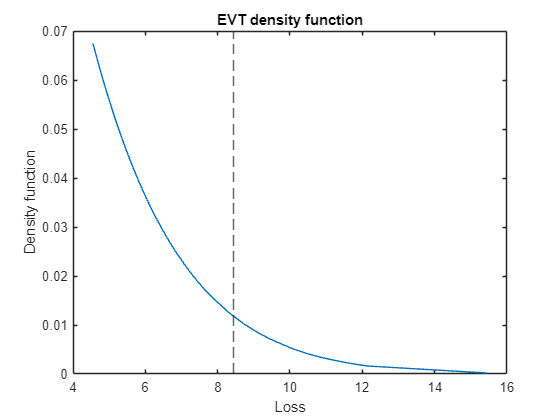

densityfunction = readmatrix('timeSeries.xlsx', 'Sheet', 'EVT', 'Range', 'H3:H84');
y_var = readmatrix('timeSeries.xlsx', 'Sheet', 'EVT', 'Range', 'D3:D84');

plot(y_var, densityfunction);
title('EVT density function')
xlabel('Loss')
ylabel('Density function')
xline(8.445554328, 'LineStyle',"--");

%--------------------------------------------------------------------------
% Task 3
%--------------------------------------------------------------------------

% Subtask a
data = readmatrix('timeSeries.xlsx', 'Sheet', 'Problem 3', 'Range', 'C4:E3429');

SP500 = data(:,1);
vix = data(:,2)/100;
libor = data(:,3)/100;
mid_4700 = ((15.70+15.84)/2)/100;
mid_4600 = ((18.23+18.33)/2)/100;
mid_4750 = ((16.19+16.30)/2)/100;
portfolio_total = mid_4700*10000+mid_4600*10000+mid_4750*20000;
q = 0.05;
h = [10000; 10000; 20000];


call_4700 = blsprice(SP500(1), 4700, libor(1), 71/365, mid_4700, q);
[~,put_4600] = blsprice(SP500(1), 4600, libor(1), 71/365, mid_4600, q);
call_4750 = blsprice(SP500(1), 4750, libor(1), 102/365, mid_4750, q);

delta_4700 = blsdelta(SP500(1), 4700, libor(1), 71/365, mid_4700, q);
[~,delta_4600] = blsdelta(SP500(1), 4600, libor(1), 71/365, mid_4600, q);
delta_4750 = blsdelta(SP500(1), 4750, libor(1), 102/365, mid_4750, q);

vega_4700 = blsvega(SP500(1), 4700, libor(1), 71/365, mid_4700, q);
vega_4600 = blsvega(SP500(1), 4600, libor(1), 71/365, mid_4600, q);
vega_4750 = blsvega(SP500(1), 4750, libor(1), 102/365, mid_4750, q);

rho_4700 = blsrho(SP500(1), 4700, libor(1), 71/365, mid_4700, q);
[~,rho_4600] = blsrho(SP500(1), 4600, libor(1), 71/365, mid_4600, q);
rho_4750 = blsrho(SP500(1), 4750, libor(1), 102/365, mid_4750, q);

gamma_4700 = blsgamma(SP500(1), 4700, libor(1), 71/365, mid_4700, q);
gamma_4600 = blsgamma(SP500(1), 4600, libor(1), 71/365, mid_4600, q);
gamma_4750 = blsgamma(SP500(1), 4750, libor(1), 102/365, mid_4750, q);

gradient_4700 = [delta_4700, vega_4700, rho_4700]';
gradient_4600 = [delta_4600, vega_4600, rho_4600]';
gradient_4750 = [delta_4750, vega_4750, rho_4750]';

G = [gradient_4700, gradient_4600, gradient_4750];

delta_SP500 = diff(SP500);
delta_vix = diff(vix);   
delta_libor = diff(libor); 

delta_matrix = [delta_SP500(1), delta_vix(1), delta_libor(1)]';

C = cov([delta_SP500, delta_vix, delta_libor]);


total_portfolio_value = h(1)*call_4700 + h(2)*put_4600 + h(3)*call_4750;

variance_portfolio = (1/(total_portfolio_value^2)) * transpose(h) * transpose(G) * C * G * h;

VaR99_1d = norminv(0.99) * sqrt(variance_portfolio) * sqrt(1/365);

% Subtask b

mc_options = norminv(0.99) * sqrt(1/365) * ((transpose(G)* C * G * h)/sqrt(variance_portfolio));

mc_rf = norminv(0.99) * sqrt(1/365) * ((C * G * h)/sqrt(variance_portfolio));

function reject = bin_test(VaR, returns, c) 
    TestLevel = 0.95;
    X_obs = 0;

   for i = 1:length(VaR)
    if ((VaR(i) + returns(i)) < 0)
        X_obs = X_obs + 1;
    end
   end 

    T = length(VaR);
    p = 1-c;
    
    Z = (X_obs - T*p)/sqrt((T*p)*(1-p));

    tailProb = 1 - normcdf(abs(Z));

    if ((tailProb*2) < (1-TestLevel))
        reject = true;
    else
        reject = false;
    end
    
end

function reject = likelihoodRatio_test(VaR, returns)
    TestLevel = 0.95;
    n_00 = 0;
    n_01 = 0;
    n_10 = 0;
    n_11 = 0;

   for i = 1:length(returns)
    diff(i) = VaR(i) + returns(i);
   end 
    
   for i = 1:length(returns)-1
        if diff(i) > 0 && diff(i+1) > 0
            n_00 = n_00 + 1;
        elseif diff(i) < 0 && diff(i+1) > 0
            n_10 = n_10 + 1;
        elseif diff(i) > 0 && diff(i+1) < 0
            n_01 = n_01 + 1;
        elseif diff(i) < 0 && diff(i+1) < 0
            n_11 = n_11 + 1;
        end
    end


    
    pUC = (n_01 + n_11) / (n_00 + n_01 + n_10 + n_11);
    p_01 = n_01 / (n_00 + n_01);
    p_11 = n_11 / (n_10 + n_11);
    
    LRatio = -2*((n_00+n_10)*log(1-pUC)+(n_01+n_11)*log(pUC)-n_00*log(1-p_01)-n_01*log(p_01)-n_10*log(1-p_11)-n_11*log(p_11));

    if chi2cdf(LRatio,1) < chi2cdf(TestLevel,1)
        reject = false;
    else
        reject = true;
    end

end
